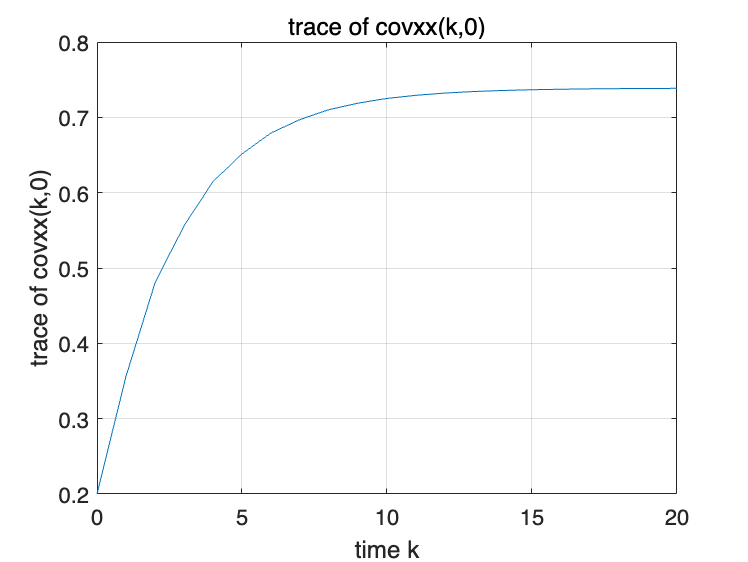

X0 = [0.1,0;0,0.1];
w=1;
v=10;
N=21;

A = [-0.08, -1; 0.7, 0.1];
B = [0.34; 0.3];
C = [0, 3];

Bw = [-0.08, -1; 0.7, 01];

N2=21;

covww=w*eye(N2);
coxvv=v*eye(N2);

covxx = cell(N2,1);
covxx5 = cell(N2,1);
covyy = cell(N2,1);
covyy5 = cell(N2,1);

covxx{1,1} = [0.1,0;0,0.1];

for k = 1:N2
    tr_covxx(k) = trace(covxx{k,1});
    covxx{k+1,1} = A * covxx{k,1} * (A.') + B * w * (B.');
    covyy{k,1} = C*covxx{k,1}*(C.')+ v;

    covxx5{k,1} = A*A*A*A*A* covxx{k,1};
    covyy5{k,1} = C*covxx5{k,1}*(C.');
end

% data1(1)=0;
% data1(2:N2+1) = cellfun(@double, covyy);
% data2(1)=0;
% data2(2:N2+1) = cellfun(@double, covyy5);
data1 = cellfun(@double, covyy);

figure();
plot(0:1:20,tr_covxx.')
title('trace of covxx(k,0)');
xlabel('time k');
ylabel('trace of covxx(k,0)');
xlim([0 20]);
grid on;

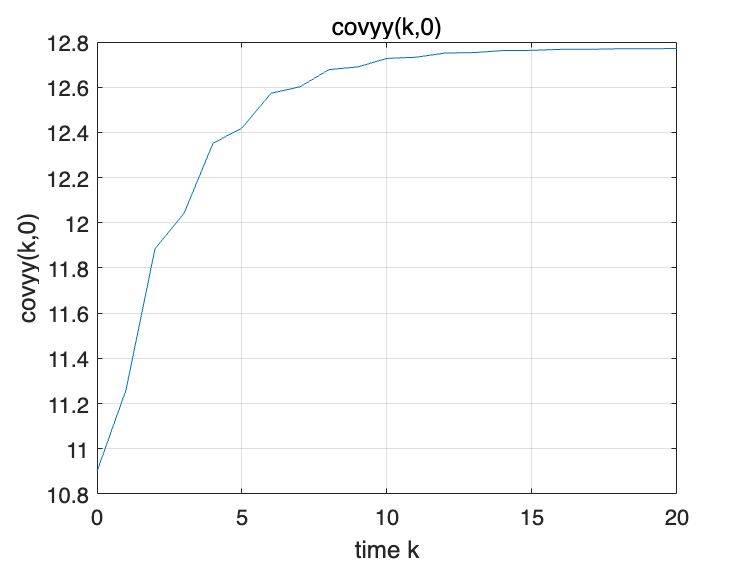



figure();
plot(0:1:20,data1)
title('covyy(k,0)');
xlabel('time k');
ylabel('covyy(k,0)');
xlim([0 20]);
grid on;

Q = B * 1 * (B.'); 
covxx0 = dlyap(A, Q)

covxx0 =     0.4308    0.0276
    0.0276    0.3080


tr_covxx0 = trace(covxx0)

tr_covxx0 = 0.7388

covyy0 = C*covxx0*(C.')+ v

covyy0 = 12.7723


delta_tr_covxx0 = tr_covxx0- tr_covxx(1,N)

delta_tr_covxx0 = 3.4898e-04

delta_covyy0 = covyy0 - data1(N)

delta_covyy0 = 0.0011